f_preobr = 350;
Control_Voltage = 1;
Source_Voltage = 150;
nagruzka.Res = 1;
nagruzka.Ind = nagruzka.Res*2/f_preobr;
E_tbl = [0 50 100];
U_u = [-1.9 -1.5 -1 -0.5 0 0.5 1 1.5 1.9];
Bridge.Vf = 2;
Bridge.Vfd = 2;
Bridge.Ron = 0.001;

tblUu = [];
tblE = [];
I_n = [];
U_n = [];
I_1 = [];
I_vt = [];
I_vtRMS = [];
U_vtmax = [];
I_vtmax = [];
gamma = [];
P_1 = [];
P_T = [];
P_n = [];


for i = 1:length(E_tbl)
    EMF = E_tbl(i);
    for j = 1:length(U_u)
        Control_Voltage = U_u(j);
        sim("lr4.slx");
        tblUu(end+1) = Control_Voltage;
        tblE(end+1) = EMF;
        I_n(end+1) = ans.nagruzkaCurrent(end);
        U_n(end+1) = ans.nagruzkaVoltage(end);
        I_1(end+1) = ans.sourceCurrent(end);
        I_vt(end+1) = ans.igbtCurrent(end);
        I_vtRMS(end+1) = ans.igbtCurrentRMS(end);
        U_vtmax(end+1) = max(ans.igbtVoltageInst);
        I_vtmax(end+1) = max(ans.igbtCurrentInst);
        gamma(end+1) = sum(ans.igbtVoltageInst == 0) / length(ans.igbtVoltageInst) * ans.SimulationMetadata.ModelInfo.StopTime;
        P_1(end+1) = Source_Voltage * I_1(end);
        P_T(end+1) = (gamma(end)*Bridge.Vf + (1-gamma(end))*Bridge.Vfd) * I_vt(end)...
            + Bridge.Ron * (I_vtRMS(end))^2;
        P_n(end+1) = U_n(end) * I_n(end);
    end
end


Tbl1 = table(tblUu.', tblE.', I_n.', U_n.', I_1.', I_vt.', I_vtRMS.', U_vtmax.', I_vtmax.', gamma.', P_1.', P_T.', P_n.');
Tbl1.Properties.VariableNames = ["Uу", "Е", "Iн", "Uн", "I1", "Ivt", "Ivt(RMS)", "Uvt(max)", "Ivt(max)", "gamma", "P1", "Pvt", "Pн"];
disp(Tbl1);

     Uу      Е         Iн            Uн           I1        Ivt      Ivt(RMS)    Uvt(max)    Ivt(max)     gamma        P1       Pvt          Pн    
    ____    ___    __________    ___________    _______    ______    ________    ________    ________    ________    ______    ______    __________

    -1.9      0       -138.43        -138.42     131.51    144.21        146           0         148       0.4875     19727    309.74         19162
    -1.5      0       -109.29        -109.28     82.107    129.64     138.34       3.784         148      0.43751

Регулировочные характеристики ШИП

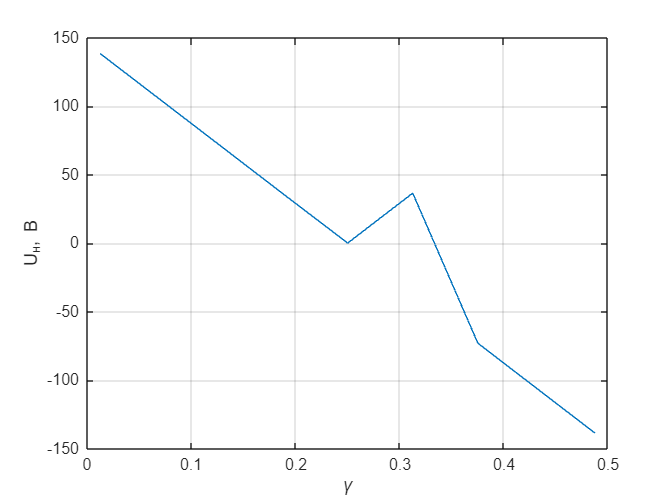

plot(gamma(1,10:18), U_n(1,10:18));
grid("on");
xlabel("\gamma");
ylabel("U_н, В");

Энергетические характеристики ШИП

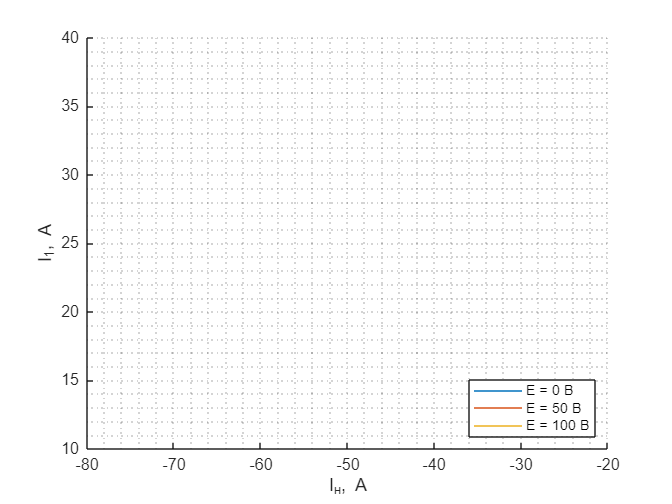

EMF_leg = ["E = 0 В", "E = 50 В", "E = 100 В"];
makeplot_lr4(I_n, I_1, "I_н, A", "I_1, A", EMF_leg);

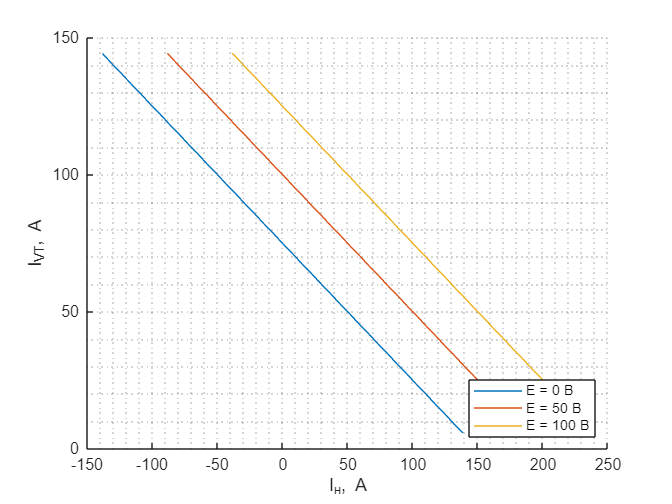

makeplot_lr4(I_n, I_vt, "I_н, A", "I_{VT}, A", EMF_leg);

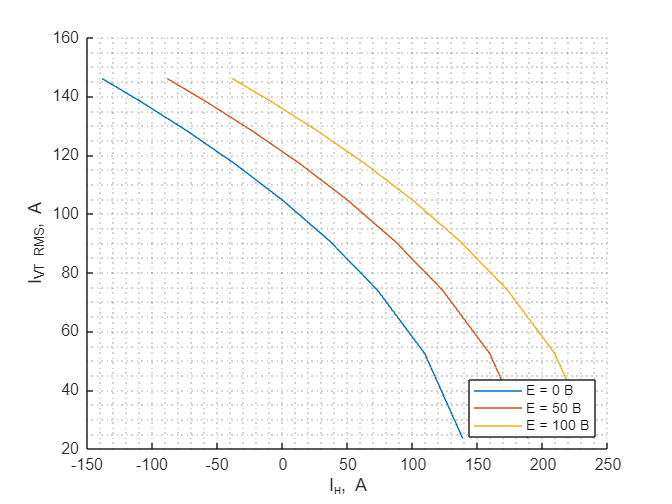

makeplot_lr4(I_n, I_vtRMS, "I_н, A", "I_{VT RMS}, A", EMF_leg);

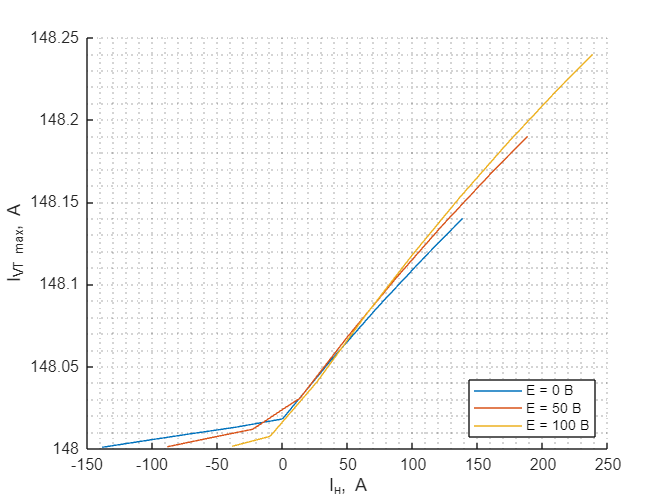

makeplot_lr4(I_n, I_vtmax, "I_н, A", "I_{VT max}, A", EMF_leg);

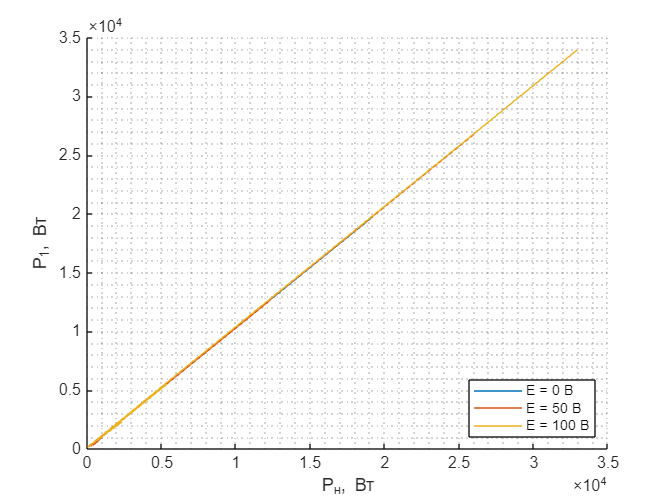

makeplot_lr4(P_n, P_1, "P_н, Вт", "P_1, Вт", EMF_leg);

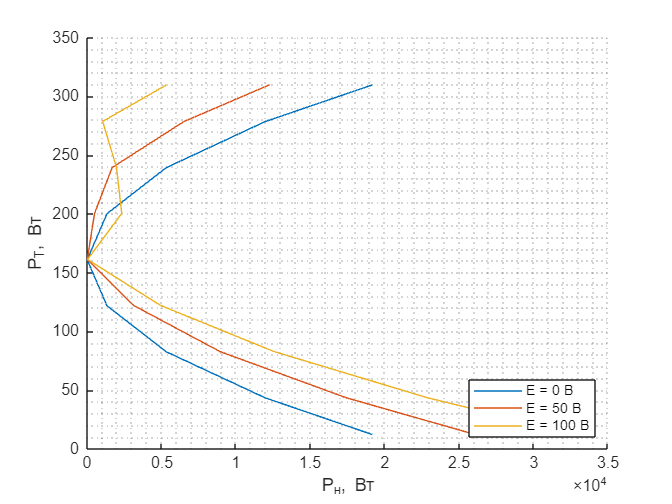

makeplot_lr4(P_n, P_T, "P_н, Вт", "P_T, Вт", EMF_leg);

Диаграммы тока питания, тока нагрузки и напряжение на нагрузки, тока и напряжения транзистора

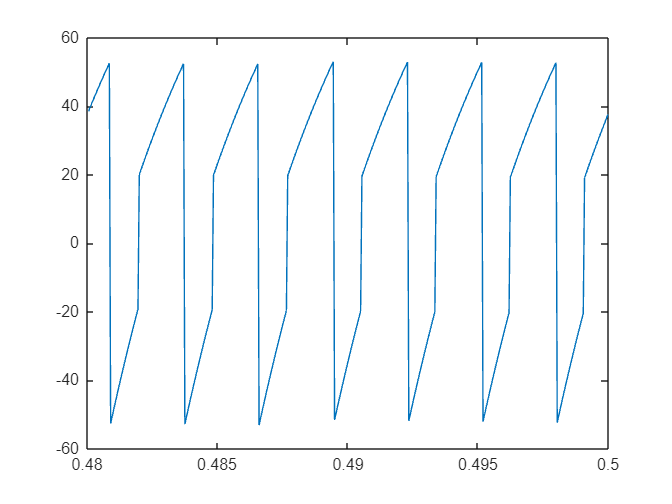

Control_Voltage = 0.5;
EMF = 0;
sim("lr4.slx");
plot(ans.Scope1.time, ans.Scope1.signals(1).values)

Control_Voltage = -0.5;
sim("lr4.slx");
